% fids=double(squeeze(mcobj.img(1,18,18,18,:)));
% dw=mcobj.DMIPara.dwell*2;
spec1=fftshift(fft(fids,2^10));
% faxis=(-size(spec1,1)/2:(size(spec1,1)/2-1) )*(1/(dw*size(spec1,1)));


            BW=1/200e-6; %Hz
            timeAxis=0:DW:(length(fid)-1)*DW;
            faxis=linspace(-BW/2,BW/2-BW/length(spec1),length(spec1));


### Manual phase correction

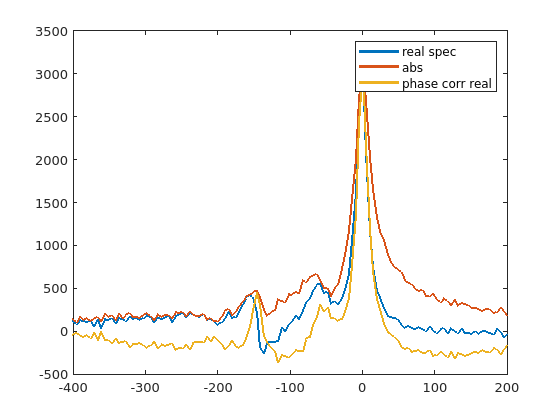

phi0=0.1;
phi1=-0.009;
% phi0=0;
% phi1=0.01; % phase evolution per Hz

 spec2=spec1(:).*exp(1i*(phi0+faxis(:).*phi1));

figure(2),clf,plot(faxis,-1*real(spec1),'LineWidth',2)
hold on
plot(faxis,abs(spec1),'LineWidth',2)
plot(faxis,-1*real(spec2),'LineWidth',2)
legend({'real spec','abs','phase corr real'})

xlim([-400 200])

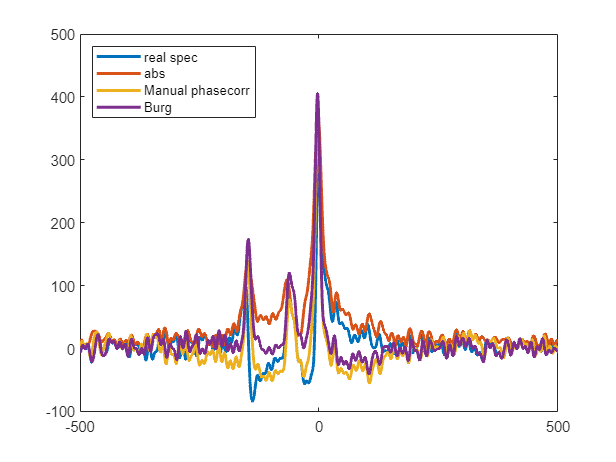

dw=mcobj.DMIPara.dwell*2; % s
%  Acqdelay=mcobj.twix.hdr.MeasYaps.alTE{1}*1e-6; %s
 Acqdelay=mcobj.twix.hdr.Phoenix.sSpecPara.lAcquisitionDelay*1e-6; %s
ext_size=round(Acqdelay/dw);
% ext_size=6;
[fid_extrap] = fidExtrp(fids(:),ext_size);
spec_extrap=fftshift(fft(fid_extrap(:),2^14)).*exp(1i*-0.8);
% faxis_extrap=linspace(-0.5/dw,0.5/dw-(2/dw)/size(spec_extrap,1) ,size(spec_extrap,1));
faxis_extrap=(-size(spec_extrap,1)/2:(size(spec_extrap,1)/2-1) )*(1/(dw*size(spec_extrap,1)));

figure(2),clf,plot(faxis,real(spec1),'LineWidth',2)
hold on
plot(faxis,abs(spec1),'LineWidth',2)
plot(faxis,real(spec2),'LineWidth',2)
plot(faxis_extrap,real(spec_extrap),'LineWidth',2)
legend({'real spec','abs','Manual phasecorr','Burg'},"Location","northwest")

xlim([-500 500])